#  Vectors 

A *vector *is an ordered  list of numbers.  The length of the vector is the number of elements it contains. 

vector = [1 3 2]

vector =      1     3     2



vector_size = length(vector)

vector_size = 3

**Zero vectors. **A *zero vector *is a vector with all elements equal to zero.

zero_vector = zeros(1,10);

**Unit vectors. **A *unit vector *is a vector with all elements equal to zero, except one element which is equal to one.

unit_vector1 = [0 0 0 1];
unit_vector2 = [0 1 0 0];

**Ones vector. **Is a vectro with all its elements equal to one.

ones_vector = ones(1,10)

ones_vector =      1     1     1     1     1     1     1     1     1     1


**Sparsity. **A vector is said to be *sparse *if many of its entries are zero; its *sparsity pattern  *is the set of indices of nonzero entries.  

In MATLAB, sparse vectors (and matrices) are used to efficiently store and manipulate large arrays that contain a significant number of zeros. This is particularly useful in applications where dealing with large-scale data with many zero elements is common.

full_vec = [0, 0, 3, 0, 4, 0, 0]

full_vec =      0     0     3     0     4     0     0


sparse_vec = sparse(full_vec)

sparse_vec =    (1,3)        3
   (1,5)        4


# **Vector addition**

Two vectors *of the same size *can be added together by adding the corresponding elements, to form another vector of the same size, called the *sum *of the vectors  

vector1 = [1, 2, 3];
vector2 = [4, 5, 6];

resultVector = vector1 + vector2;

**Geometric representation**

% Define the vectors
vec1 = [4, 5];
vec2 = [1, -2];

% Calculate the resultant vector
R = vec1 + vec2

R =      5     3


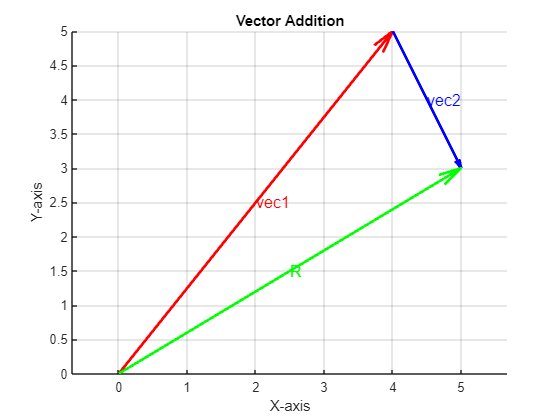


% Create a figure
figure
hold on
grid on
axis equal

% Plot vector A (red)
quiver(0, 0, vec1(1), vec1(2), 1, 'r', 'LineWidth', 2)

% Plot vector B (blue), starting from the head of A
quiver(vec1(1), vec1(2), vec2(1), vec2(2), 1, 'b', 'LineWidth', 2)

% Plot the resultant vector R (green)
quiver(0, 0, R(1), R(2), 1, 'g', 'LineWidth', 2)

% Label the vectors
text(vec1(1)/2, vec1(2)/2, 'vec1', 'FontSize', 12, 'Color', 'r')
text(vec1(1) + vec2(1)/2, vec1(2) + vec2(2)/2, 'vec2', 'FontSize', 12, 'Color', 'b')
text(R(1)/2, R(2)/2, 'R', 'FontSize', 12, 'Color', 'g')

% Add title and labels
title('Vector Addition')
xlabel('X-axis')
ylabel('Y-axis')

# **Scalar-vector multiplication**

Another operation is *scalar multiplication *or *scalar-vector multiplication*, in which a vector is multiplied by a scalar ( *i.e.*, number), which is done by multiplying every element of the vector by the scalar.

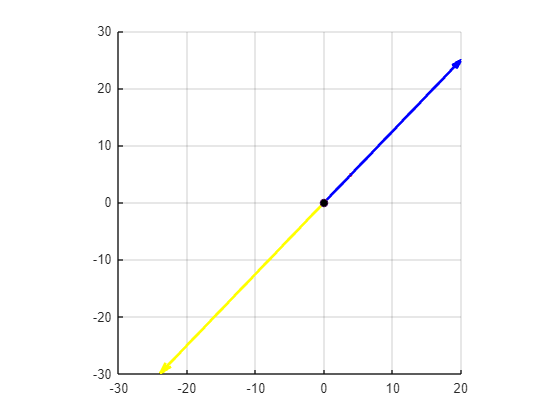

scalar1 = randi(5,1);
scalar2 = -randi(10,1);

scaledVector1 = scalar1 * vec1;
scaledVector2 = scalar2 * vec1;

figure
hold on
axis square
grid on


quiver(0, 0, vec1(1), vec1(2), 1, 'r', 'LineWidth', 2)
quiver(0, 0, scaledVector1(1), scaledVector1(2), 1, 'b', 'LineWidth', 2)
quiver(0, 0, scaledVector2(1), scaledVector2(2), 1, 'y', 'LineWidth', 2)

plot(0,0,'o',MarkerFaceColor= 'k');

# Vector magnitude and unit vector

The magnitue of length of norm of a vector is calculated by taking the square root of sum of the squares of the elements of a vector. I Eucludian spaces meaning 1D, 2D and 3D spaces it is simply the geometric distance between tail to head of the vector. 

vecMag = norm(vec1);     % The length of vec1

Unit vector is any vector which its magnitued is 1. We can change the length of any vector by dividing all elements of the vector by its magnitude.

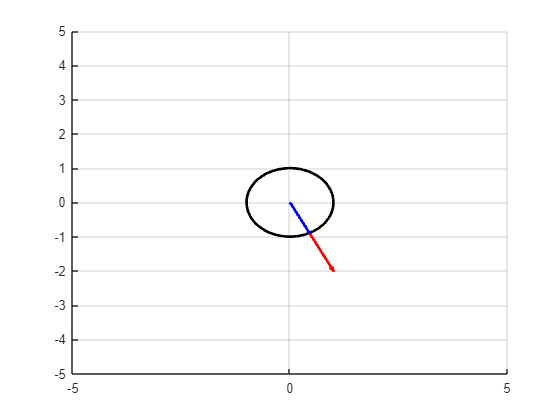

randVec = randi([-5,5],2,1);   % A random vector in 2D
randVecNorm = norm(randVec);  % Its norm    
randVecUnit = randVec/randVecNorm;  % Corresponding unit vector

% Visual Proof

figure
hold on
grid on

viscircles([0 0],1,Color='k');
quiver(0,0,randVec(1),randVec(2),1,'r',LineWidth=2)
quiver(0,0,randVecUnit(1),randVecUnit(2),1,'b',LineWidth=2)

xlim([-5 5])
ylim([-5 5])

# **Inner product**  

The *inner product *(also called *dot product*) of two *n*-vectors is defined as the scalar, sum of the products of corresponding entries.

vec1 = [1,3,4,3];
vec2 = [3,2,3,3];

dot(vec1,vec2)

ans = 30

Examples:

*• ****Sum. ***The inner product of a vector with the vector of ones gives the sum of the elements of the vector.

randVect = randi(5,4,1);
onesVect = ones(1,4);

sum(randVect) == dot(randVect,onesVect)

ans = logical
   1


*•**** Average.***  The inner product of an *n*-vector with the vector  **1/***n *gives the average or mean of the elements of the vector. 

randVect = randi(5,4,1);
onesVect = ones(1,4)/4;

mean(randVect) == dot(randVect,onesVect)

ans = logical
   1


*• ****Sum of squares.***  The inner product of a vector with itself gives the sum of the squares of the elements of the vector.

randVect = randi(5,4,1);

sum(randVect.^2) == dot(randVect,randVect)

ans = logical
   1


*• ****Selective sum. ***Let *b *be a vector all of whose entries are either 0 or 1. Then the inner product of b and a is the sum of the elements in *a *for which *b**i *= 1  

#### **Geometry of inner product**

From the geomtry perspective, the dot product of two vectors is equal to the product of their magnitudes and the cosine of the angle between them. The algebraic and geometric definition of dot product are mathematically equivalent but expressed in different forms. Notice that vector magnitudes are strictly positive quantities, while the cosine of an angle can range between -1 and +1. This means that the sign of the dot product is determined entirely by the geometric relationship between the two vectors.

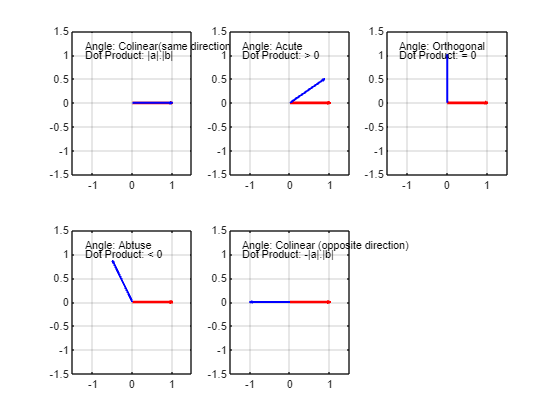

% Geometric illustration of dot product
a = [1, 0];   % choosing the first vector fixed and on the x-axis

angles = [0, pi/6, pi/2, 2*pi/3, pi];   % angles for different conditions
condText = {'Colinear(same direction)', 'Acute', 'Orthogonal','Abtuse','Colinear (opposite direction)'};  % Conditions
dotProducts = {'|a|.|b|','> 0', '= 0', '< 0', '-|a|.|b|'};


for angle_i = 1:length(angles)
    b_i = [cos(angles(angle_i)), sin(angles(angle_i))];
    dotProduct_i = norm(a) * norm(b_i) * cos(angles(angle_i));

    ax = subplot(2, 3, angle_i);
    
    q1 = quiver(0, 0, a(1), a(2), 1, 'r', 'LineWidth',2);
    hold on;
    q2 = quiver(0, 0, b_i(1), b_i(2), 1, 'b', 'LineWidth', 1.5);
    text(-1.2, 1.2, ['Angle: ' , condText{angle_i}], 'Color', 'k', 'FontSize', 8);
    text(-1.2, 1, ['Dot Product: ', dotProducts{angle_i}], 'Color', 'k', 'FontSize', 8);   
    ax.XLim = [-1.5, 1.5];
    ax.YLim = [-1.5, 1.5];
    grid on
    
end

# Orthogonal Vector Decomposition

vector decomposition means breaking up a vector into simpler pieces which can make it easer to work with, just like breaking up a number into it's prime factors. One of the most important decompositions in linear algebra is orthogonal decomposition in which we break up vector **v **into two vectors, one colinear to the reference  vector **u** ( here we name it **projVontoU** the other orthogonal to **u** (here we name it **w**).

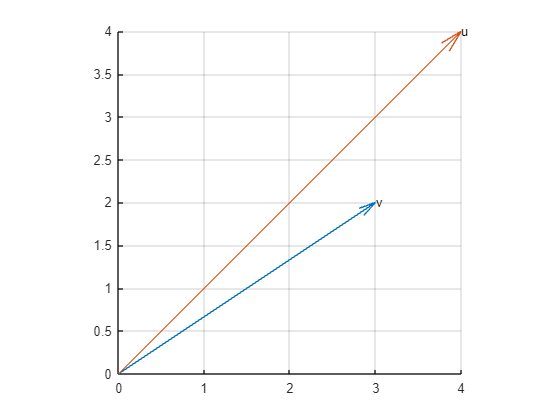

v = [3, 2];
u = [4, 4];
names = {'v','u'};

figure
hold on
grid on
axis square


quiver(0 ,0, v(1), v(2), 1);
text([v(1),u(1)], [v(2), u(2)], names, "FontSize",10);
quiver(0 ,0, u(1), u(2), 1);

We can find the projectin of **v **onto **u **by a simple formula:

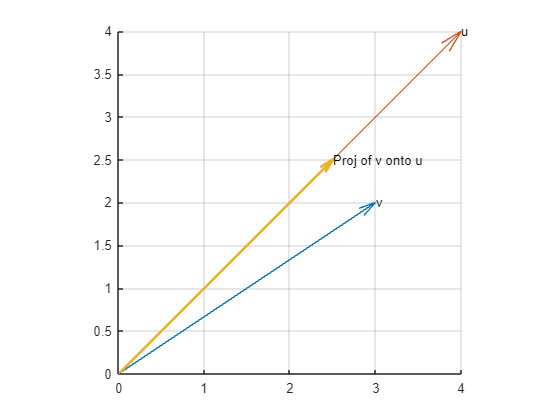

projVontoU = (dot(u,v)/dot(u,u)) * u;
names = {'v','u','Proj of v onto u'};

figure
hold on
grid on
axis square

quiver(0 ,0, v(1), v(2), 1);
quiver(0 ,0, u(1), u(2), 1);
quiver(0,0,projVontoU(1), projVontoU(2),1,LineWidth=2);
text([v(1),u(1), projVontoU(1)], [v(2), u(2),projVontoU(2)] ,names, "FontSize",10);

Finding the other component which orthogonal to **projVontoU** is easy. We call it **w**.

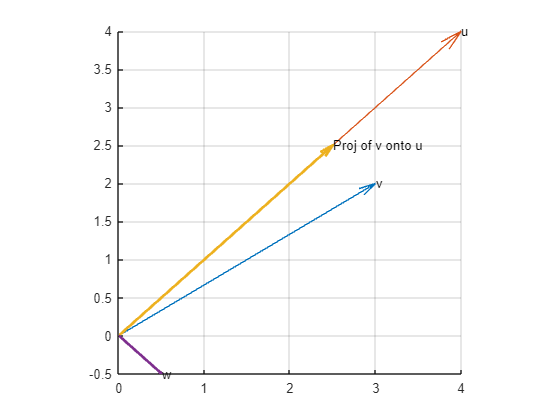

w = v - projVontoU;
names = {'v','u','Proj of v onto u','w'};

figure
hold on
grid on
axis square

quiver(0 ,0, v(1), v(2),1)
quiver(0 ,0, u(1), u(2), 1)
quiver(0,0,projVontoU(1), projVontoU(2),1,LineWidth=2)
quiver(0 ,0, w(1), w(2), 1,LineWidth=2)

text([v(1),u(1), projVontoU(1), w(1)], [v(2), u(2),projVontoU(2),w(2)] ,names, "FontSize",10)

To show that **projVontoU** and **w** are orthogonal their dot product must be equal to zero. Also we if add them toghether the result should be **v**.

dot(w,projVontoU)

ans = 0

(projVontoU + w) - v

ans =      0     0


# **Linear combinations.**

 If ***a****1, . . . ,****a****m *are *n*-vectors, and ***β***1, . . .* ,****β****m *are scalars, the *n*-vector

                                                        ***β***1***a***1 + *· · · *+ ***β****n****a****n*

is called a *linear combination *of the vectors ***a***1, . . . ,***a****n*.   

# Linear independence

A set of vectors are **linearly** **independent **if non of the vectors can be written as a linear combination of other vectors. Otherwise that set is **linearly dependent**.

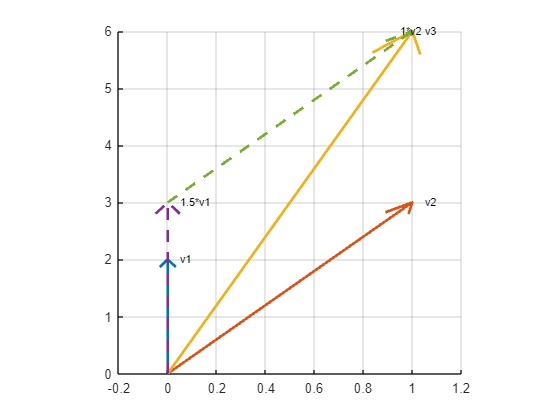

% A set of linearly dependent vectros in 2D 
v1 = [0 2];
v2 = [1 3];
v3 = [1 6];   % v3 = 1.5 * v1 + v2
textOffset = .05;
% Geomtrically we can 'construct' v3 with weighted sum of v1 and v2

figure
axis square
grid on
hold on
quiver( 0, 0, v1(1),v1(2),1,LineWidth=2)
quiver( 0, 0, v2(1),v2(2),1,LineWidth=2)
quiver( 0, 0, v3(1),v3(2),1,LineWidth=2)
quiver( 0, 0, 1.5*v1(1),1.5*v1(2),1,LineStyle="--",LineWidth=2)
quiver(1.5*v1(1), 1.5*v1(2), v2(1), v2(2), 1,LineStyle="--", LineWidth=2)
text([v1(1)+textOffset v2(1)+textOffset v3(1)+textOffset 1.5*v1(1)+textOffset 1.5*v1(1)+v2(1)-textOffset],[v1(2) v2(2) v3(2) 1.5*v1(2) 1.5*v1(2)+v2(2)],{'v1','v2', ...
    'v3','1.5*v1','1*v2'},"FontSize",8)
grid on

# Subspace and Span

When we have a set of independent vectors, then all possible linear combination of them is called a **vector sucbspace** and the action of creating this subspace is named **span**. So subspace and span are related conceptes, we can think about subscpace as noun and span as verb. 

Dinmension of a vector space is equal to the number of independent vectros in that subspace. For example when we have 2 independent vectors in 3D, then our vector subspace is 2D. 

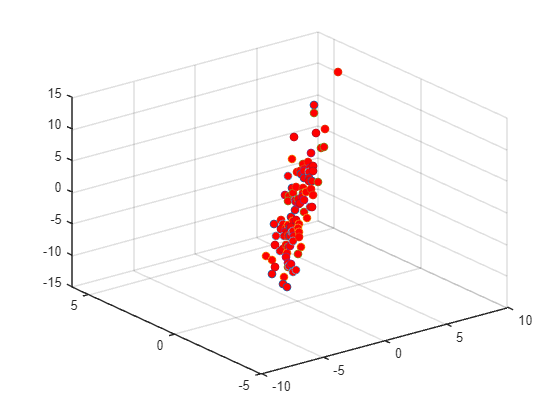

% Create two independent vectors in 3D
v1 = [1 0 4];
v2 = [3 2 1]; 

% Generate 100 random linear combinations of these vectors to show that the
% subspace is 2D plane

randWeights = randn(2,100);

figure
for i = 1:length(randWeights)
    vectorTip = randWeights(1,i).*v1 + randWeights(2,i).*v2;
    scatter3(vectorTip(1),vectorTip(2),vectorTip(3),MarkerFaceColor='r')
    hold on
end

# Basis Vectors

A basis vectors  set of vectors that we use to describe vectors quntitatively like any physical properties that needs a unit any vector also needs a basis to be decribed. When we wirte [3,2] as vector, by default, we mean the vector is according to standard Cartesian basis in 2D: [1,0], [0,1]. We mean that our vector is 3 times [1,0] and 2 times [0,1].

The choice of basis vectors to describe a vector is arbitrary as long as it has two properties: To describe the vectors in a subspace the vectors in that subspace needs to 1) span all vectors in that subspace 2) be linearly independent.